# Homework5 Code

## Question 5.51

a=conv([1 -1],[1 0 0.49]);
b=conv([1 -1.5 -1],[1 0.9]);
% n = 512
% [H1,w]=freqz(b,a,[-pi:2*pi/n:pi]);
% plot(w/pi,abs(H1));
% xlabel('\omega/\pi'),ylabel('|H(e^{j\omega})|'),grid 
% ax = gca;
% ax.YLim = [-0 50];
% figure()
%  
len = 50

len = 50

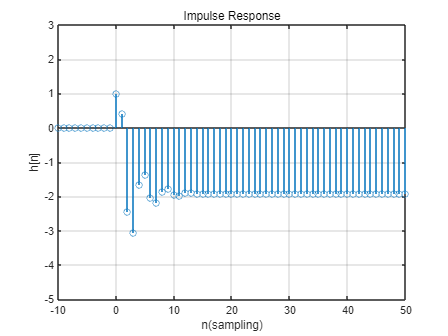

x1=[zeros(1,10) 1 zeros(1,len)];
[y,~]=filter(b,a,x1);
stem(-10:len, y)
xlabel('n(sampling)'),ylabel('h[n]'),title('Impulse Response'),grid 
ax = gca;
ax.YLim = [-5 3];
ax.XLim = [-10 len];

figure()


## Exercise 1.2

% len = 100
% x1=[zeros(1,10) 1 zeros(1,len)];
% a=[1 -1.8*cos(pi/16) 0.81];
% b=[1 0.5];
% zs=roots(b);
% zs
% ps=roots(a);
% ps
% [y,zf]=filter(b,a,x1);
% stem(-10:len, y)
% xlabel('n(sampling)'),ylabel('h[n]'),title('Impulse Response'),grid 
% ax = gca;
% ax.YLim = [-3 5];
% ax.XLim = [-10 len];
% figure()


## Exercise 1.2

% (a)
n = 512

n = 512

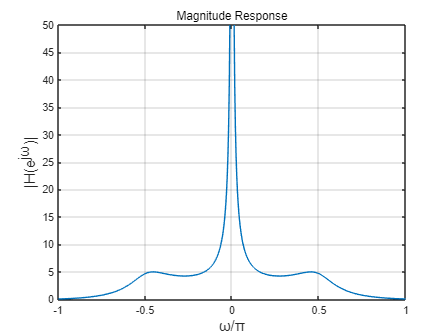

[H1,w]=freqz(b,a,[-pi:2*pi/n:pi]);
plot(w/pi,abs(H1));
xlabel('\omega/\pi'),ylabel('|H(e^{j\omega})|'), title('Magnitude Response'),grid 
ax = gca;
ax.YLim = [-0 50];

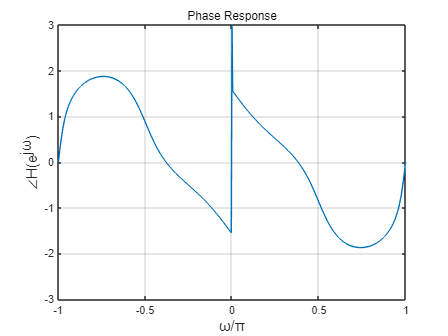

figure()

plot(w/pi,angle(H1));
xlabel('\omega/\pi'),ylabel('\angle{H(e^{j\omega})}'), title('Phase Response'),grid 
xlim([-1.00 1.00])
ylim([-3.00 3.00])

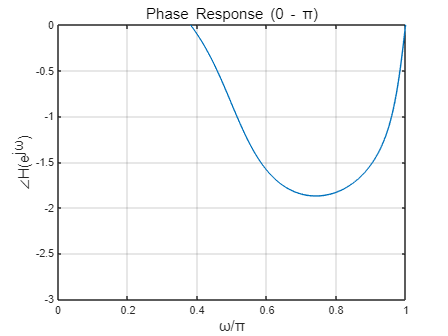

figure()

% (b)
plot(w/pi,angle(H1));
xlabel('\omega/\pi'),ylabel('\angle{H(e^{j\omega})}'), title('Phase Response (0 - \pi)'),grid 
xlim([0.00 1.00])
ylim([-3.00 0.00])

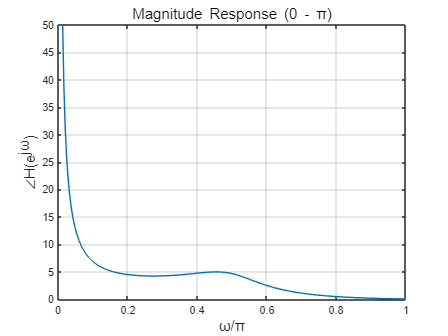

figure()

plot(w/pi,abs(H1));
xlabel('\omega/\pi'),ylabel('\angle{H(e^{j\omega})}'), title('Magnitude Response (0 - \pi)'),grid 
xlim([0.00 1.00])
ylim([0.00 50.00])

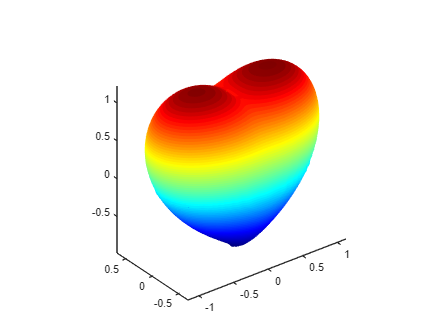

figure()




[x,y,z]=meshgrid(linspace(-1.5,1.5)); 
f=@(x,y,z)(x.^2 + (9/4)*y.^2 + z.^2 - 1).^3 - x.^2.*z.^3 - (9/80)*y.^2.*z.^3; 
p=patch(isosurface(x,y,z,f(x,y,z),0)); view(3);axis equal 
set(p,'FaceVertexCData',jet(size(get(p,'faces'),1)) ,'FaceColor', 'flat', 'EdgeColor', 'none');